clear all
load ARTEMIS.mat;
load ARTEMIS_road.mat
load WLTC.mat
load eff_interpol.mat

my_cycle(1,:)=linspace(30,0,1001);
my_cycle(2,:)=[my_cycle(1,1:end-1)-my_cycle(1,2:end),0];
my_cycle(3,:)=3;

start=0;%Definisci l'istante iniziale
N=2; %Time horizon
u=[];
%eff_int();
%definisci le opzioni per l'optimisation
opts=optimoptions('fmincon','MaxFunctionEvaluations',1e3,...
    'Algorithm','sqp','ConstraintTolerance',1e-3,'Display','none','FiniteDifferenceType','forward');
    
SOC=0.41*ones(N,1);
u_n=0*ones(N,1);
N_rounds=3;
N_it=1000;
driving_cycle=ARTEMIS;

%u=zeros(1,N_it*N_rounds);
tic
x=zeros(N_rounds,1);
C=[eye(N);-eye(N)];
d=[-ones(N,1);-ones(N,1)];

for k=1:N_rounds
     %Se si vuole cambiare ciclo tra un round e l'altro
     %x(k)=rand;
     %driving_cycle=(x(k)<0.33)*ARTEMIS+(x(k)>=0.33)*ARTEMIS_road*(x(k)<=0.66)+(x(k)>0.66)*my_cycle;
    for j=1:N_it-N
        %Estrai i sottovettori e ridefinisci gli handle per i sottovettori.
        %Stavolta la funzione di costo è calcolata tutta in una volta. Bisogna
        %rivedere la funzione di costo bene
       
        speed=driving_cycle(1,start+j:start+N-1+j);
        acceleration=driving_cycle(2,start+j:start+N-1+j);
        gear=driving_cycle(3,start+j:start+N-1+j);
        
        StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input,F1,F2);
        myFullStateUpdate=@(u)my_full_horizon(u,SOC(2),StateUpdate);
        FullStateUpdate=@(u)full_horizon(u,SOC(2),StateUpdate);

        %%
myoptions               =   myoptimset;
myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =   1e-5;
myoptions.tolgrad    	=	1e-8;
myoptions.ls_beta       =	0.2;
myoptions.ls_c          =	.01;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e3;
myoptions.xsequence     =	'on';
myoptions.tolconstr     =   1e-2;
myoptions.display       =  'iter';
        %%
        
        %calcoli la u ottima sull'orizzonte dei 5 secondi
        [u_n,~,~,exitf(j),~,entrato(j)]=myfmincon(myFullStateUpdate,[u_n(2:end);mean(u_n)],[],[],C,d,1*N,4*N,myoptions);
        if exitf(j)<=0
            popoop=1;%[u_n]=myfmincon(myFullStateUpdate,[u_n(2:end),0]',[],[],C,d,1*N,4*N,myoptions);
        end

        %salvi la u per poi vedere il risultato complessivo
        u(j+(k-1)*N_it)=u_n(1);
        if exitf(j)<=0
            fprintf("All'iterazione %d l'exitflag è %d ",j,exitf(j))
        end
    
        if rem(j,N_it/10)==0
            fprintf("Siamo al: %f percento dell'iterazione %d \n Ci ha messo %f \n",j/(N_it)*100,k,toc)
            tic
        end
    
        [~,SOC]=FullStateUpdate(u_n);
    end
end

Siamo al: 10.000000 percento dell'iterazione 1 
 Ci ha messo 6.001413 
Siamo al: 20.000000 percento dell'iterazione 1 
 Ci ha messo 1.155709 
Siamo al: 30.000000 percento dell'iterazione 1 
 Ci ha messo 1.146063 
Siamo al: 40.000000 percento dell'iterazione 1 
 Ci ha messo 1.186363 
Siamo al: 50.000000 percento dell'iterazione 1 
 Ci ha messo 1.164205 
Siamo al: 60.000000 percento dell'iterazione 1 
 Ci ha messo 1.431230 
Siamo al: 70.000000 percento dell'iterazione 1 
 Ci ha messo 0.630337 
Siamo al: 80.000000 percento dell'iterazione 1 
 Ci ha messo 0.982327 
Siamo al: 90.000000 percento dell'iterazione 1 
 Ci ha messo 1.294584 
Siamo al: 10.000000 percento dell'iterazione 2 
 Ci ha messo 2.510317 
Siamo al: 20.000000 percento dell'iterazione 2 
 Ci ha messo 1.140254 
Siamo al: 30.000000 percento dell'iterazione 2 
 Ci ha messo 1.048618 
Siamo al: 40.000000 percento dell'iterazione 2 
 Ci ha messo 1.708444 
Siamo al: 50.000000 percento dell'iterazione 2 
 Ci ha messo 1.865948 
Siamo 

sum(entrato)

ans = 3

toc

Elapsed time is 1.217054 seconds.


%Vedi i risultati utilizzando la u trovata nell'intero orizzonte
speed=[];
acceleration=[];
gear=[];

for i=1:k
    %driving_cycle=(x(i)<0.33)*ARTEMIS+(x(i)>=0.33)*ARTEMIS_road*(x(i)<=0.66)+(x(i)>0.66)*my_cycle;
    speed=[speed,driving_cycle(1,start+1:start+N+j)];
    acceleration=[acceleration,driving_cycle(2,start+1:start+N+j)];
    gear=[gear,driving_cycle(3,start+1:start+N+j)];
end
StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input,F1,F2);
FullStateUpdate=@(u)full_horizon(u,SOC(1),StateUpdate);
[cost,SOC2plot,T_req,T_giv,mf,I_c,V_c,Tm]=FullStateUpdate(u);
[c,ceq]=nonlinconstr(u,SOC(1),StateUpdate);
tot_c=sum(sum(c<=0))/(4*length(c))

tot_c = 1

tot_ceq=sum(abs(ceq)<=opts.ConstraintTolerance)/length(ceq)

tot_ceq = 1

tot_mf=sum(mf)

tot_mf = 0.4588

tot_soc_var=SOC(1)-SOC(end)

tot_soc_var = -6.1056e-06

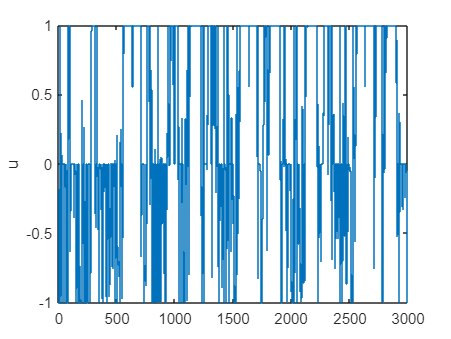

stairs(u)
ylabel('u')

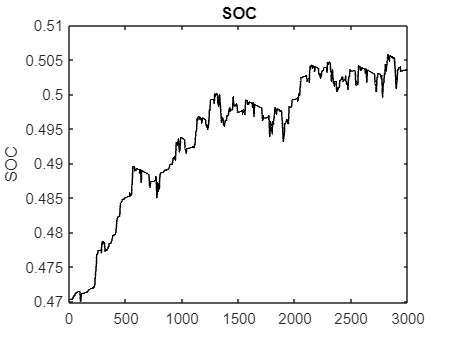

figure
hold on
num_segments = length(x); % Number of regions
segment_size = length(SOC) / num_segments; % Elements per segment
colors = [1 1 0; 1 0 0; 0 1 0]; % Define colors (red, green, blue)

% for i = 1:num_segments
%     % Define segment range
%     x_start = (i - 1) * segment_size + 1;
%     x_end = i * segment_size;
% 
%     % Determine background color based on x(i)
%     if x(i) < 0.33
%         bg_color = colors(1, :); % Light red
%     elseif x(i) < 0.66
%         bg_color = colors(2, :); % Light green
%     else
%         bg_color = colors(3, :); % Light blue
%     end
% 
%     % Plot background as a filled rectangle
%     fill([x_start x_end x_end x_start], [min(SOC) min(SOC) max(SOC) max(SOC)], ...
%         bg_color, 'EdgeColor', 'none');
% end

% Plot the SOC data on top
plot(SOC2plot, 'k', 'LineWidth', 1);
% Additional plot settings
ylabel('SOC');
title('SOC');
box on;
hold off

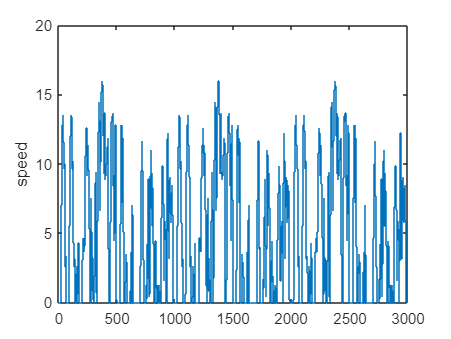


stairs(speed)
ylabel('speed')

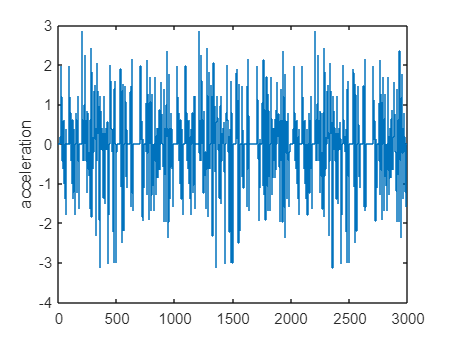

stairs(acceleration)
ylabel('acceleration')

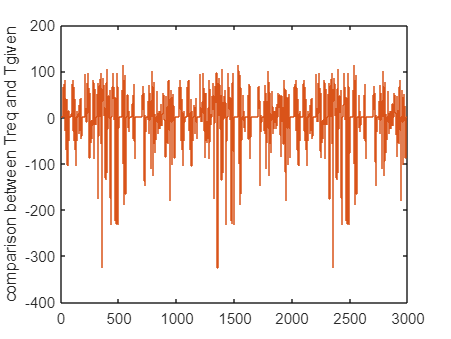

stairs(T_giv)
hold on
stairs(T_req)
hold off
ylabel('comparison between Treq and Tgiven')